# Projeto - Eletromagnetismo e Ondulatória

## Modelando Antena Emissora

ant = spiralArchimedean('Turns', 5) % entre 3 e 6 voltas

ant =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


ant.NumArms = 1; % número de braços (ramos)  = 1
ant.Tilt = 90; % Inclinação da antena plano 3D
ant.TiltAxis = "Y"

ant =   spiralArchimedean with properties:

             NumArms: 1
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


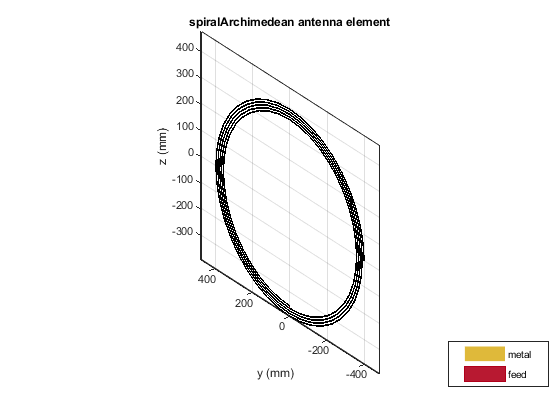

ant.OuterRadius = 40e-2; 
ant.InnerRadius = 35e-2;
show(ant)

## Impedância da Antena

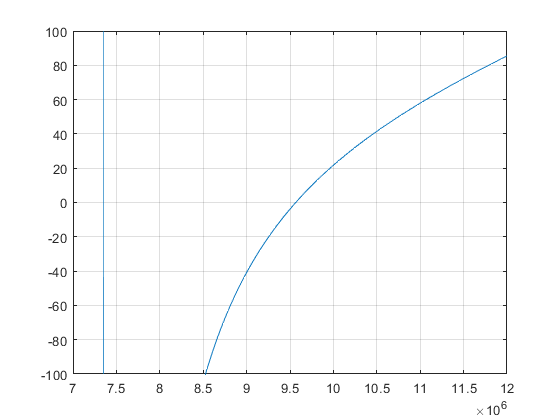

f = linspace(6e6, 12e6, 100);

impedancia = impedance(ant,f);
imaginario = imag(impedancia);
plot(f,imaginario)
ylim([-100, 100])
grid


% Impedância nula = f = 9545450
% Wc = 4437190

## Modelando Antena Receptora

ant2 = spiralArchimedean('Turns', 5) % entre 3 e 6 voltas

ant2 =   spiralArchimedean with properties:

             NumArms: 2
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


ant2.NumArms = 1; % número de braços (ramos)  = 1
ant2.Tilt = 90; % Inclinação da antena plano 3D
ant2.TiltAxis = "Y"

ant2 =   spiralArchimedean with properties:

             NumArms: 1
               Turns: 5
         InnerRadius: 5.0000e-04
         OuterRadius: 0.0398
    WindingDirection: 'CCW'
                Tilt: 90
            TiltAxis: 'Y'
                Load: [1×1 lumpedElement]


ant2.OuterRadius = 40e-2; 
ant2.InnerRadius = 35e-2;
show(ant2)

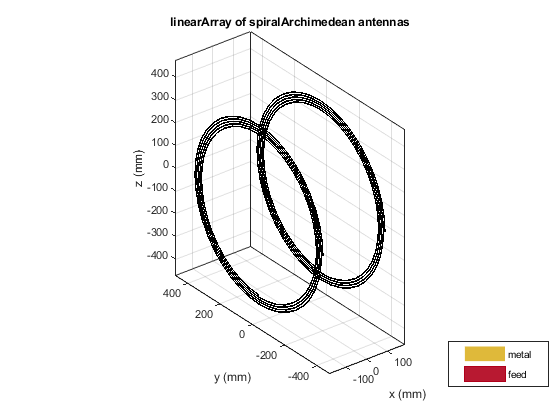



% Element Space
la = linearArray;
la.Element = [ant, ant2];
la.ElementSpacing = .3;
show(la);

## Simulando o Acoplamento

sd = sparameters(la, f)

sd =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [100×1 double]
     Parameters: [2×2×100 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


## Visualizando os Ganhos

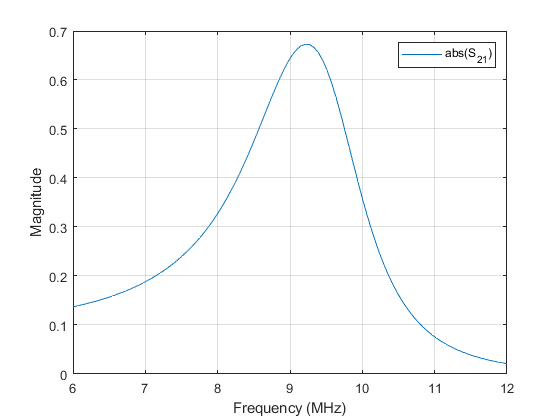

rfplot(sd,2,1,'abs')

gains = abs(rfparam(sd,2,1));
max_gain = abs(max(gains))

max_gain = 0.6731

Essa frequência é especial pois é a de ressonância (amplifica o ganho). A relação é a de que, a maior magnitude é aquela com frequência semelhante a de ressonância do gráfico de impedâncias, ou seja, o ponto em que a parte imaginária da impedância é zero.

#### Criando array de ganhos

% ganho = abs(rfparam(sd,2,1)) % exemplo de vetor ganho
spacing = linspace(5e-2, 1, 20)'; % Variando para as diferentes distâncias
disp(length(spacing))

    20



gains = zeros(length(spacing), length(f))

gains =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     


for i=1:length(spacing)
    la.ElementSpacing = spacing(i);
    sd = sparameters(la, f);
    gains(i,:) = abs(rfparam(sd,2,1));
end

#### Gráfico 

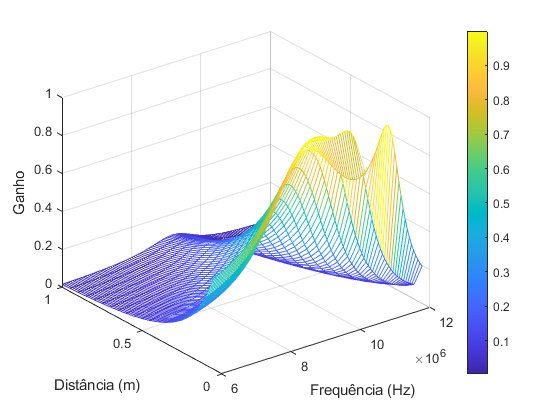

mesh(f, spacing, gains)
colorbar
xlabel('Frequência (Hz)')
ylabel('Distância (m)')
zlabel('Ganho')

## Corrente Ressonante

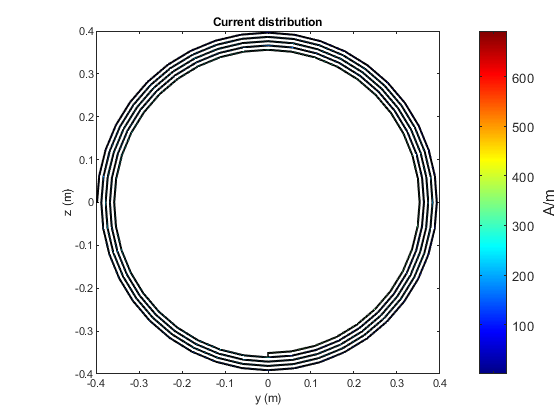

current(ant2,9545450)